## Turning Radius Path Comparison

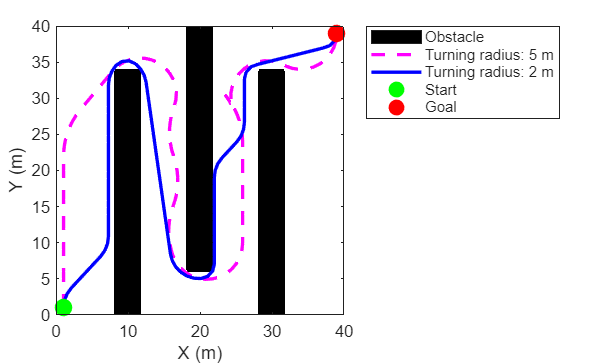

clear; clc; close all;

% Grid & resolution
res = 5;                         % cells per meter
H = 200; W = 200;                % grid size in cells (~40 m x 40 m)
occ = zeros(H, W);               % 0 free, 1 occupied

% Parameters
barCenters   = [50 100 150];     % x positions (in cells)
barWidth     = 15;               % bar thickness (cells)
gapHeight    = 30;               % opening height (cells) ~ gapHeight/res meters
clearancePad = 2;                % extra free rows around gap (cells)

% Build 3 bars with alternating top/bottom gaps
for i = 1:numel(barCenters)
    x1 = barCenters(i) - floor(barWidth/2);
    x2 = x1 + barWidth - 1;
    x1 = max(1, x1); x2 = min(W, x2);

    if mod(i,2)==1
        % Odd bar: TOP gap
        topFreeRows = 1 : (gapHeight+clearancePad);
        occRows = (max(topFreeRows)+1) : H;
    else
        % Even bar: BOTTOM gap
        botFreeRows = (H-gapHeight-clearancePad+1) : H;
        occRows = 1 : (min(botFreeRows)-1);
    end
    occ(occRows, x1:x2) = 1;
end

% Build occupancy map
map = binaryOccupancyMap(occ, res);

% Optional inflation
inflate(map, 0.4);

% State space & validator
ss = stateSpaceSE2;
ss.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];
sv = validatorOccupancyMap(ss);
sv.Map = map;

% Two planners with different params
planner  = plannerHybridAStar(sv, MinTurningRadius=5, MotionPrimitiveLength=7);
planner1 = plannerHybridAStar(sv, MinTurningRadius=2, MotionPrimitiveLength=3);

% Start and goal
startPose = [1 1 pi/2];   % [meters, meters, radians]
goalPose  = [39 39 pi/2];

% Plan both paths
refpath  = plan(planner, startPose, goalPose, SearchMode='exhaustive');  
refpath1 = plan(planner1, startPose, goalPose, SearchMode='exhaustive'); 

% Plot map + both paths
figure;
show(map); 
hold on;

% Add dummy obstacle entry to legend (solid black square)
patch(NaN, NaN, 'k', 'DisplayName', 'Obstacle');

% Extract states
pathXY  = refpath.States(:,1:2);
pathXY1 = refpath1.States(:,1:2);

% Plot both
plot(pathXY(:,1),  pathXY(:,2),  'm--', 'LineWidth', 2, 'DisplayName','Turning radius: 5 m');
plot(pathXY1(:,1), pathXY1(:,2), 'b-','LineWidth', 2, 'DisplayName','Turning radius: 2 m');

% Plot start/goal markers
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor','g', 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 10, 'MarkerFaceColor','r', 'DisplayName','Goal');

legend('Location','bestoutside');
xlabel('X (m)');
ylabel('Y (m)');
title('');
hold off;

## Inflated Obstacal Visualisaion

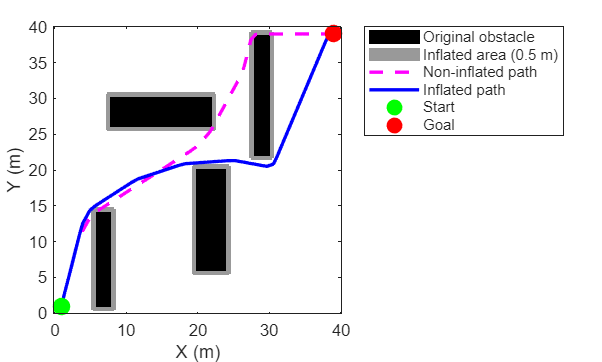

%% Build base occupancy map
res = 5; % cells per meter
occ = zeros(200,200);
% Rectangular obstacles (rows = y, cols = x)
occ(130:195,  30:40)   = 1;  
occ(50:70,    40:110)  = 1;   
occ(100:170,  100:120) = 1;  
occ(7:90,     140:150) = 1;   

% Create baseline map (no inflation)
mapNoInflate = binaryOccupancyMap(occ, res);

% Create inflated map (0.5 m)
mapInflate = binaryOccupancyMap(occ, res);
inflate(mapInflate, 0.5);

%% Shared state space & poses
ss = stateSpaceSE2;
ss.StateBounds = [mapNoInflate.XWorldLimits; mapNoInflate.YWorldLimits; [-pi pi]];
svNo = validatorOccupancyMap(ss); svNo.Map = mapNoInflate;
svIn = validatorOccupancyMap(ss); svIn.Map = mapInflate;

plannerNo = plannerHybridAStar(svNo, ...
    MinTurningRadius=1.0, MotionPrimitiveLength=0.5);
plannerIn = plannerHybridAStar(svIn, ...
    MinTurningRadius=1.0, MotionPrimitiveLength=0.5);

startPose = [1 1 pi/2];
goalPose  = [39 39 0];

%% Plan both paths
pathNo = plan(plannerNo, startPose, goalPose, SearchMode="exhaustive");
pathIn = plan(plannerIn, startPose, goalPose, SearchMode="exhaustive");

%% Create custom visualization showing original and inflated obstacles
figure;

% Get the occupancy matrices
occOriginal = getOccupancy(mapNoInflate);
occInflated = getOccupancy(mapInflate);

% Create a 3-level map: 0 = free, 1 = inflated only, 2 = original obstacle
customMap = zeros(size(occOriginal));
customMap(occInflated == 1) = 1;  % Inflated areas (grey)
customMap(occOriginal == 1) = 2;  % Original obstacles (black)

% Display the custom map (flip vertically to match world coordinates)
imagesc(mapNoInflate.XWorldLimits, mapNoInflate.YWorldLimits, flipud(customMap));
colormap([1 1 1; 0.6 0.6 0.6; 0 0 0]); % white, grey, black
axis xy; axis equal; axis tight;
xlabel('X (m)'); ylabel('Y (m)');
hold on;

% Extract XY paths
pNo = pathNo.States(:,1:2);
pIn = pathIn.States(:,1:2);

% Plot paths
plot(pNo(:,1), pNo(:,2), 'm--', 'LineWidth', 2, 'DisplayName','No Inflate');
plot(pIn(:,1), pIn(:,2), 'b-', 'LineWidth', 2, 'DisplayName','Inflated (0.5 m)');

% Start/goal markers
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1), goalPose(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

% Create custom legend entries for the map colors
% Create custom legend entries for the map colors (rectangular patches)
h1 = patch(NaN, NaN, 'k', 'EdgeColor', 'k', 'DisplayName', 'Original obstacle');
h2 = patch(NaN, NaN, [0.6 0.6 0.6], 'EdgeColor', [0.6 0.6 0.6], 'DisplayName', 'Inflated area (0.5 m)');

legend([h1, h2, findobj(gca, 'DisplayName', 'No Inflate'), ...
        findobj(gca, 'DisplayName', 'Inflated (0.5 m)'), ...
        findobj(gca, 'DisplayName', 'Start'), ...
        findobj(gca, 'DisplayName', 'Goal')], ...
       {'Original obstacle', 'Inflated area (0.5 m)', 'Non-inflated path', 'Inflated path', 'Start', 'Goal'}, ...
       'Location', 'bestoutside');

hold off;

## Inflation Path Comparison

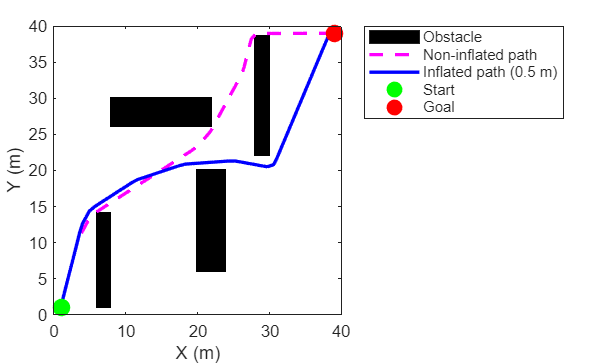

%% Build base occupancy map
res = 5; % cells per meter
occ = zeros(200,200);

% Rectangular obstacles (rows = y, cols = x)
occ(130:195,  30:40)   = 1; 
occ(50:70,    40:110)  = 1;   
occ(100:170,  100:120) = 1;   
occ(7:90,     140:150) = 1;  

% Create baseline map (no inflation)
mapNoInflate = binaryOccupancyMap(occ, res);

% Create inflated map (0.5 m)
mapInflate = binaryOccupancyMap(occ, res);
inflate(mapInflate, 0.5);

%% Shared state space & poses
ss = stateSpaceSE2;
ss.StateBounds = [mapNoInflate.XWorldLimits; mapNoInflate.YWorldLimits; [-pi pi]];

svNo = validatorOccupancyMap(ss); svNo.Map = mapNoInflate;
svIn = validatorOccupancyMap(ss); svIn.Map = mapInflate;

plannerNo = plannerHybridAStar(svNo, ...
    MinTurningRadius=1.0, MotionPrimitiveLength=0.5);

plannerIn = plannerHybridAStar(svIn, ...
    MinTurningRadius=1.0, MotionPrimitiveLength=0.5);

startPose = [1 1 pi/2];
goalPose  = [39 39 0];

%% Plan both paths
pathNo = plan(plannerNo, startPose, goalPose, SearchMode="exhaustive");
pathIn = plan(plannerIn, startPose, goalPose, SearchMode="exhaustive");

%% Plot both on one figure
figure; show(mapNoInflate); hold on;
title('') % Blank title

% Add dummy obstacle entry to legend (solid black square)
patch(NaN, NaN, 'k', 'DisplayName', 'Obstacle');

% Extract XY paths
pNo = pathNo.States(:,1:2);
pIn = pathIn.States(:,1:2);

% Plot paths
plot(pNo(:,1), pNo(:,2), 'm--', 'LineWidth', 2, 'DisplayName','Non-inflated path');
plot(pIn(:,1), pIn(:,2), 'b-', 'LineWidth', 2, 'DisplayName','Inflated path (0.5 m)');

% Start/goal markers
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1), goalPose(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

xlabel('X (m)'); 
ylabel('Y (m)');

legend('Location','bestoutside');
hold off;